# Least-Squares Deconvolution Problem with Infinite Solutions

Create two vectors, each with two elements, and convolve them using the `"valid"` option. This option returns only those parts of the convolution that are computed without the zero-padded edges. In this case, the convolved signal `y` has only one element.

xin = [-1 2];
h = [2 5];
y = conv(xin,h,"valid")

Find the least-squares deconvolution of convolved signal `y` with respect to impulse response `h`. With the `"valid"` option, `deconv` does not always return the original signal in `x`, but it returns the solution of the deconvolution problem that minimizes `norm(x)` instead.

[x,r] = deconv(y,h,"valid",Method="least-squares")

To check the solution, you can find the full convolution of the computed signal `x` with `h`. The central part of this convolved signal is the same as the original `y` that defined the deconvolution problem.

yfull = conv(x,h,"full")

In this problem, `deconv` returns a different signal than the original signal because it solves for one equation with two variables, which is $-1 = 5\cdot x(1) + 2 \cdot x(2)$. This system is *underdetermined*, meaning this system has more variables than equations. This system has infinite solutions when using the least-squares method to minimize the residual norm, or `norm(y - conv(x,h,"valid"))`, to 0. For this reason, `deconv` also finds a solution that minimizes `norm(x)`.

The following figure illustrates the situation for this underdetermined problem. The blue line represents the infinite number of solutions to the equation $x(2) = -1/2 - 5/2\cdot x(1)$. The orange circle represents the minimum distance from the origin to the line of solutions. The solution returned by `deconv` lies at the tangent point between the line and circle, indicating the solution closest to the origin.

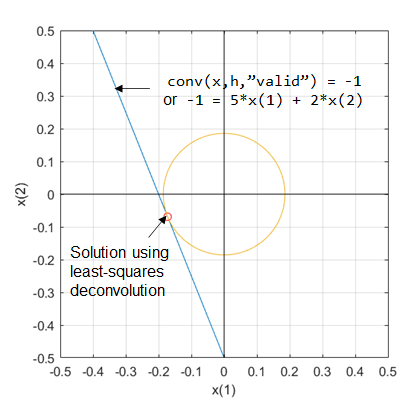

*Copyright 2023 The MathWorks, Inc.*